# 6. Num processo industrial de fabrico de chips, alguns aparecem defeituosos tornando-os inapropriados para comercializacao. E sabido que em media por cada 1000 chips ha um defeituoso

## (a) Usando a distribuicao binomial, determine a probabilidade de numa amostra de 8000 chips aparecerem 7 defeituosos.

%1000 chips -> 1 defeituoso, ou seja, p(defeituoso) = 1/1000

n = 8000;
N = 1e4;
p = 1 / 1000;
k = 7;

lancamentos = rand(n,N) < p;
sucessos = sum(lancamentos) == k;
pX = sum(sucessos)/N;
fprintf("px: %f%", pX);

px: 0.134900

%pB(k) = nCk * p^k * (1-p)^(n-k) = n! / (k! * (n-k)!) * p^k * (1-p)^(n-k)


## (b) Determine a mesma probabilidade usando a aproximacao de Poisson e compare o resultado com o da alinea anterior.

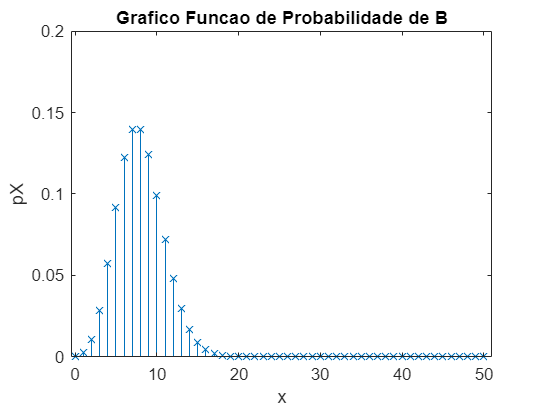

pBT = zeros(1,51);
for k=0 : 50
  nCk = prod(n:-1:n-k+1)/prod(1:k);
  pBT(k+1) = nCk * p^k * (1-p)^(n-k);
end

x = 0:50;
stem(x,pBT,'x');

axis([-0.5 51 0 0.2]);
xlabel('x');
ylabel('pX');
title("Grafico Funcao de Probabilidade de B");

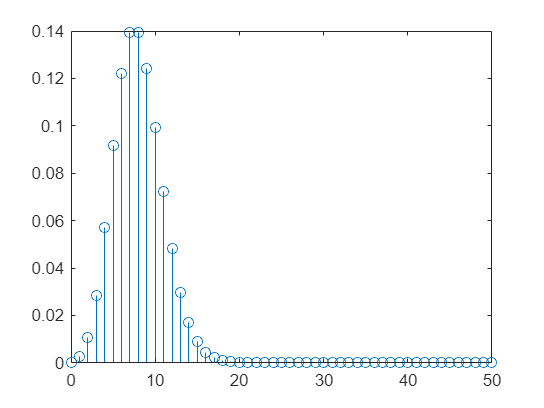

m = 8;
pBS = zeros(1,51);
for k=0 : 50
  pBS(k+1) = leiPoisson(m,k);
end

stem(x,pBS,'o');